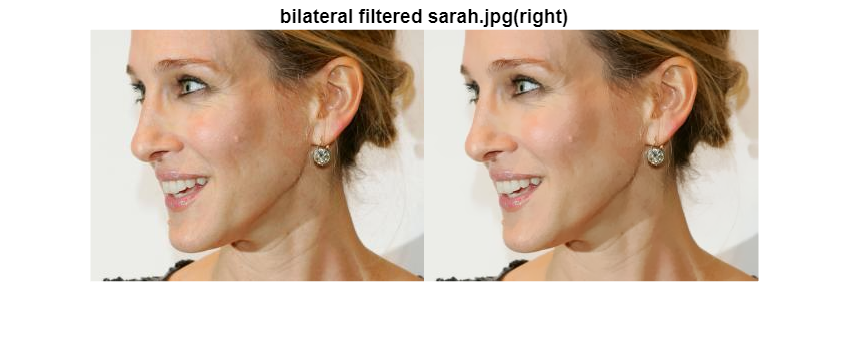

Isarah = double(imread("sarah.jpg"));

g = bilat_filtering(Isarah, 4, 5);
figure
imshowpair(uint8(Isarah), uint8(g), "montage"), title("bilateral filtered sarah.jpg(right)");

% bilat_filtering() function input: 
% Image (double) : an image to apply filter to 
% Sigma_s (double) : sigma spatial for determining spatial weight
% Sigma_i (double) : sigma intensity for determinging range weight

% return: bilatF (double) : filtered image

function bilatF = bilat_filtering(Image, Sigma_s, Sigma_i)
    [height, width, channels] = size(Image);
    filtered_I = zeros(size(Image));
    Snorm = 2 * Sigma_s^2;
    Inorm = 2 * Sigma_i^2;

    for i = 1:height
        for j = 1:width
            Ip = Image(i, j, :);            % Find center intensity (RGB values)
            tmp = zeros(1, 1, channels);    % Total filtered value accumulated in each round
            Wp = 0;                         % Total weight for normalization in the end

            halfwid = 3 * max(Sigma_s, Sigma_i); % Half-width of the kernel

            for u = -halfwid:halfwid
                for v = -halfwid:halfwid
                    Qx = i + u;
                    Qy = j + v;
                    if (Qx > 0 && Qx <= height && Qy > 0 && Qy <= width)    % check for neighbor validity
                        Iq = Image(Qx, Qy, :);

                        Gs = exp(-(u^2 + v^2) / Snorm);
                        Gi = exp(-sum((Ip - Iq).^2) / Inorm); % compute intensity difference for RGB

                        Wcurrent = Gs * Gi;                   % calculate weight at current pixel
                        tmp = tmp + Wcurrent * Iq;
                        Wp = Wp + Wcurrent;                   % update total weight
                    end
                end
            end
            filtered_I(i, j, :) = tmp / Wp;      % final filtered value after normalization
        end
    end

    % output retains double for now
    bilatF = filtered_I;
end


function bilatF = bilat_filtering_grey(Image, Sigma_s, Sigma_i)
    filtered_I = zeros(size(Image, 1), size(Image, 2));

    for i = 1:size(Image, 1)
        for j = 1:size(Image, 2)
            Ip = Image(i, j); % Find center intensity
            tmp = 0; % Total filtered value accumulated in each round
            Wp = 0; % Total weight for normalization in the end

            halfwid = 3 * max(Sigma_s, Sigma_i); % Half-width of the kernel

            for u = -halfwid:halfwid
                for v = -halfwid:halfwid
                    Qx = i + u;
                    Qy = j + v;
                    if (Qx > 0 && Qx <= size(Image, 1) && Qy > 0 && Qy <= size(Image, 2)) % check for neighbor validity
                        Iq = Image(Qx, Qy);

                        Gs = exp(-(u^2 + v^2) / (2 * Sigma_s^2));           % spatial weight
                        Gi = exp(-(Ip - Iq)^2 / (2 * Sigma_i^2));           % range weight

                        Wcurrent = Gs * Gi;                         % weight at current neighbor
                        tmp = tmp + Wcurrent * Iq;                  % filtered pixel value
                        Wp = Wp + Wcurrent;                         % add up all pixel weights for a total weight
                    end
                end
            end
            filtered_I(i, j) = tmp / Wp;                % normalize current filtered value
        end
    end

    % output double for now
    bilatF = filtered_I;
end
